api = "https://archive-api.open-meteo.com/v1/archive?latitude=51.07&longitude=3.10&start_date=2022-02-08&end_date=2023-02-07&daily=temperature_2m_max,temperature_2m_min,temperature_2m_mean&timezone=Europe%2FBerlin";
s = webread(api);

max_temperature = s.daily.temperature_2m_max;
mean_temperature = s.daily.temperature_2m_mean;
min_temperature = s.daily.temperature_2m_min;

mean_mean = mean(mean_temperature)

mean_mean = 12.1638

mean_max = mean(max_temperature);
mean_min = mean(min_temperature);

U_glas = 1.7;
U_deur = 2.9;
U_muur = 1;
height = 3;

t_binnen = 22.5;
omtrek_muur = 52.44;
omtrek_raam = 12;
omtrek_deur = 5.94;

Q=height*(t_binnen - mean_temperature)*(omtrek_muur*U_muur + omtrek_raam*U_glas+omtrek_deur*U_deur)

Q = 1.0e+03 *

    3.4585
    3.6477
    4.2691
    4.9446
    5.1608
    4.5663
    3.6477
    4.1881
    3.0262
    3.4856


mean(Q)

ans = 2.7928e+03

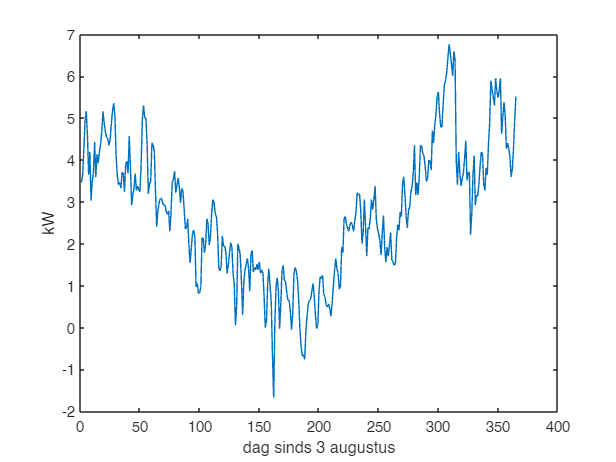

plot(Q*10^(-3))
xlabel("dag sinds 3 augustus")
ylabel("kW");

gas = 165997;
elek_dag = 50148;
elek_nacht = 24952;

verbruikt_totaal = gas+elek_dag+elek_nacht

verbruikt_totaal = 241097


berekend = sum(Q*10^(-3)*24)

berekend = 2.4465e+04

verbruikt_totaal-berekend

ans = 2.1663e+05

verbruik_verwarmer = 15*10^3;
temp_sauna = 90;
A_raam = 1*0.5

A_raam = 0.5000

A_sauna = 2.78*2

A_sauna = 5.5600

A_sm = 2*4.78

A_sm = 9.5600

A_plafond = 13.862

A_plafond = 13.8620

R_tot =  1.05;
U_sauna=1/R_tot

U_sauna = 0.9524

U_sm = 1/(1/U_sauna + 1/U_muur)

U_sm = 0.4878

U_sr = 1/U_glas + 1/U_sauna

U_sr = 1.6382

Q_muur = (A_raam*U_sr+A_sauna*U_sauna+A_sauna*U_sm)*(temp_sauna-t_binnen)

Q_muur = 595.7922

Q_plafond = A_plafond*U_sauna*(temp_sauna-t_binnen)

Q_plafond = 891.1286

Q_tot = Q_plafond+Q_muur

Q_tot = 1.4869e+03

## Opstart van sauna

Lineaire benadering

t_begin = 22; %[C]
t_eind = 90; %[C]
t_gem = mean([t_begin t_eind]); 

tijd_opwarming = 3600; % [s]

AU_totaal_binnen = A_raam*U_sr+A_sauna*U_sauna+A_sauna*U_sm+A_plafond*U_sauna

AU_totaal_binnen = 22.0285

AU_totaal_buiten = (U_sr*1.2*3+U_sm*(1.14+0.56)*3)

AU_totaal_buiten = 8.3855

% Q_out = (t_gem-t_binnen)*AU_totaal + 
Q_in = 7500;


volume = (4.78-0.15)*(2.90-0.15)*2.5 %[m^3]

volume = 31.8313

rho = 1.23 %[kg/m^3]

rho = 1.2300

cp = 1005 %[J/kg K]

cp = 1005

syms T(t)
cond = T(0) == t_begin+273

$$cond = T\left(0\right)=295$$

ode = diff(T,t)*rho*volume*cp==Q_in-AU_totaal_binnen*(T-(t_binnen+273))-AU_totaal_buiten*(T-(mean_min +273));

TSol(t) = dsolve(ode, cond)

$$TSol(t) = \frac{8107777933826035652377183854775}{15060237569357340448028360704}-\frac{3665007850865620220208817447095\,{\mathrm{e}}^{-\frac{214018848074564125\,t}{276888339766132604928}}}{15060237569357340448028360704}$$

T_inverse = finverse(TSol);
vpa(TSol(60)-273)

$$ans = 33.028337978385566029915190990532$$

vpa(T_inverse(90+273))/60

$$ans = 7.0662038059186036873976506875948$$

verbruik = 15000*vpa(T_inverse(90+273))*5* 2.77777778 * 10^(-7)*0.70*4

$$verbruik = 24.731713340500484320865814063815$$

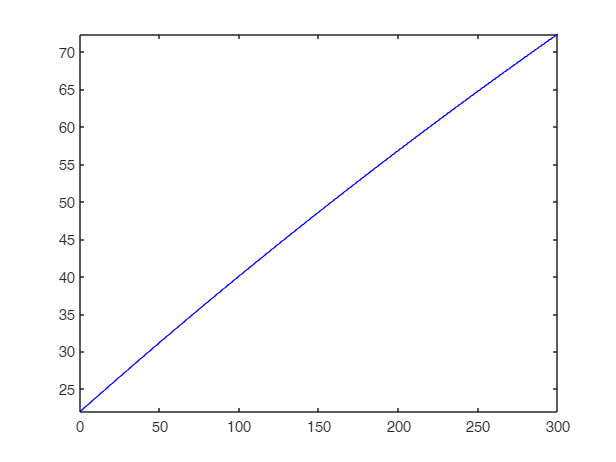

fplot(@(t) TSol(t)-273,[0 300],'b')

% t= thermal_mass*(t_eind-t_begin)/(Q_in)
